# **TU: Linear Regression**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Fit Linear Regression

## Include path

addpath('../IAIA/Library')  

# Examples

## Example 1: Fit with Linear Regression 

### **Data Acquisition**

- Feature: One-Dimension,  p=1

- True value: ytrue = 2X+3

x = randn(100,1);
y = x*2 + 3+randn(100,1);

### **Fit Linear Regression**

mdl = fitlm(x,y)

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     2.8064     0.10256    27.364    1.0981e-47
    x1              1.7411     0.10865    16.025    3.9373e-29


관측값 개수: 100, 오차 자유도: 98
RMS 오차: 1.02
결정계수: 0.724, 수정된 결정계수: 0.721
상수 모델에 대한 F-통계량: 257, p-값 = 3.94e-29

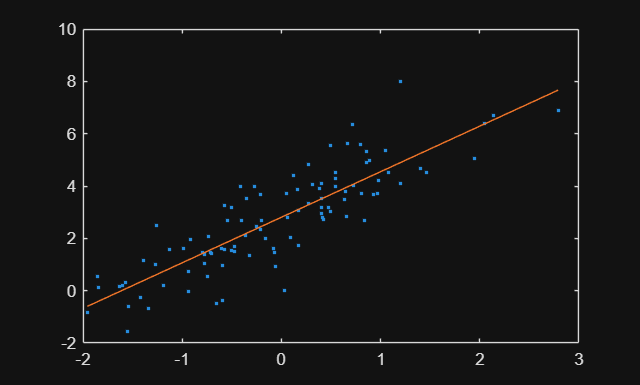


% Plot prediction
plot(x,y,'.',x,mdl.Fitted, '-')

### **Analyze Linear Regression**

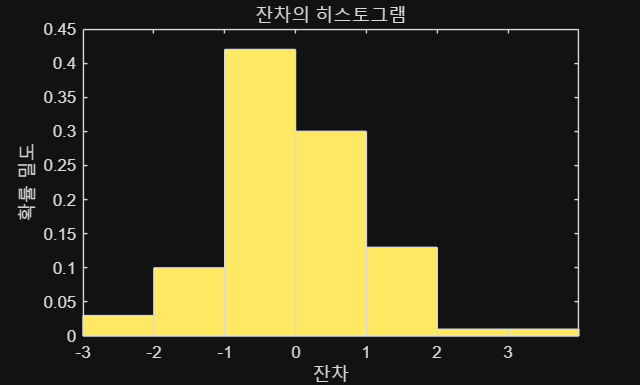

% Plot residual histogram
plotResiduals(mdl)


% From remove outlier from histogram
outl = find(abs(mdl.Residuals.Raw) > 2);
mdl.Residuals.Raw(outl)

ans =    -2.8716
   -2.1631
    3.1093
    2.2915
   -2.1770



% Fit with outlier removed
mdl2 = fitlm(x,y,'Exclude',outl)

mdl2 = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     2.8199     0.088838    31.742    1.0825e-51
    x1              1.6495     0.093168    17.704    1.5399e-31


관측값 개수: 95, 오차 자유도: 93
RMS 오차: 0.864
결정계수: 0.771, 수정된 결정계수: 0.769
상수 모델에 대한 F-통계량: 313, p-값 = 1.54e-31

### **Predict with Test data**

% Ypredict and confidence interval
Xnew=2;
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 6.1189

YnewI =     5.6989    6.5388


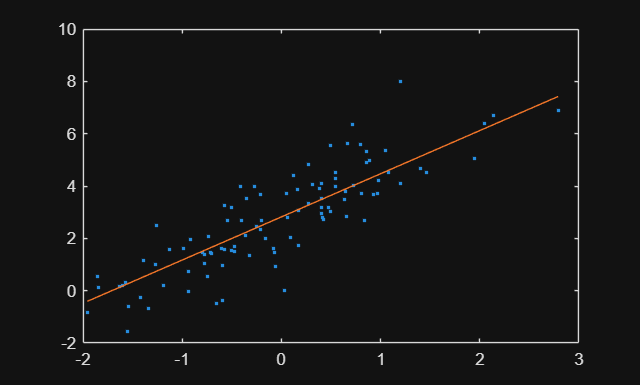


% Plot prediction
plot(x,y,'.',x,mdl2.Fitted, '-')

## Example 2: Predict Car MPG

Find linear relationship of  MPG(연비) with   Weight & Displacement

Then, Predict MPG for a car with Weight=3000 , Displacement=300

### **Data Acquisition**

-  Dependet Variable:  MPG

- Independet Variables: Weight, Displacement

clear
load carsmall

tbl = table(MPG,Weight, Displacement);  % table type

### **Fit  Linear Regression**

mdl = fitlm(tbl,'MPG~Weight+Displacement')

mdl = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate        SE         tStat       pValue  
                    __________    _________    _______    __________

    (Intercept)         46.925       2.0858     22.497    6.0509e-39
    Weight          -0.0068422    0.0011337    -6.0353    3.3838e-08
    Displacement     -0.014593    0.0082695    -1.7647      0.080968


관측값 개수: 94, 오차 자유도: 91
RMS 오차: 4.09
결정계수: 0.747, 수정된 결정계수: 0.741
상수 모델에 대한 F-통계량: 134, p-값 = 7.22e-28

mdl.CoefficientNames

ans = 1×3 cell 배열
    {'(Intercept)'}    {'Weight'}    {'Displacement'}


mdl.Coefficients.Estimate

ans =    46.9247
   -0.0068
   -0.0146


### **Analyze Linear Regression**

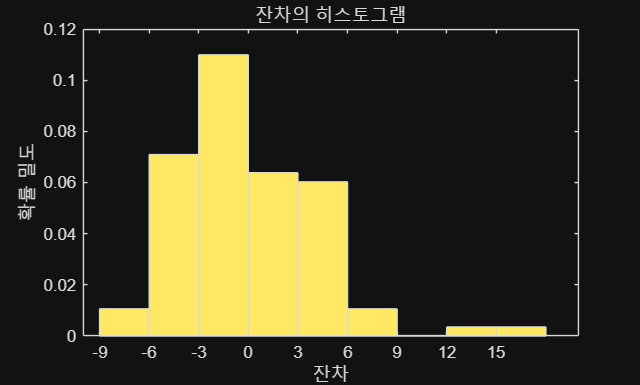

plotResiduals(mdl)


% Remove outlier
outl = find((mdl.Residuals.Raw) > 9);

% Fit with outlier removed
mdl2 = fitlm(tbl,'MPG~Weight+Displacement','Exclude',outl)

mdl2 = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate         SE         tStat       pValue  
                    __________    __________    _______    __________

    (Intercept)         45.548        1.8056     25.226    2.5559e-42
    Weight          -0.0062503    0.00097845    -6.3879    7.4767e-09
    Displacement     -0.018035     0.0071414    -2.5255      0.013324


관측값 개수: 92, 오차 자유도: 89
RMS 오차: 3.51
결정계수: 0.796, 수정된 결정계수: 0.792
상수 모델에 대한 F-통계량: 174, p-값 = 1.78e-31

mdl2.Coefficients.Estimate

ans =    45.5477
   -0.0063
   -0.0180


### **Predict**

Detailed look at the interactions 

% Ypredict and confidence interval
Xnew=[3000 300]; 
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 21.3863

YnewI =    19.8515   22.9211


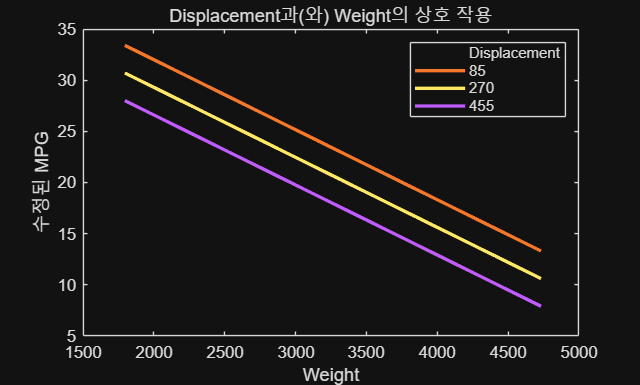


plotInteraction(mdl,'Displacement','Weight','predictions')

# Exercise

## Exercise 1 :  Gradient Descent

**Linear Regression Using Gradient Descent**

Hypothesis. 

To find the parameters, repeat until convergence

where, cost(error) function

and

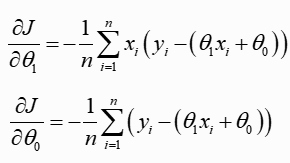

### **Data Acquisition**

Feature: One-Dimension,  p=1

True: y = 2X+3

N=100;
X = randn(N,1);
Y = X*2 + 3+randn(N,1);



### **Fit Linear Regression:  Gradient Descent**

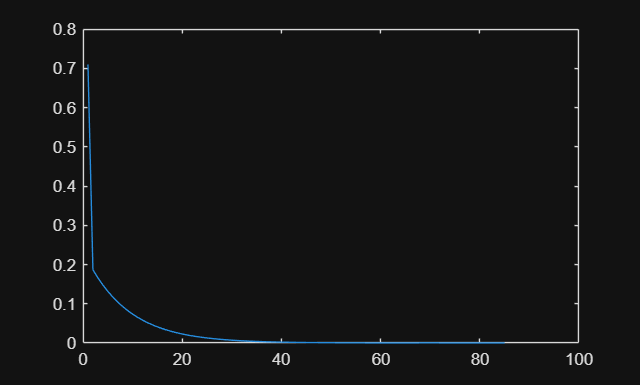

% dJ/dx
lamda=0.1;  % learning rate

% Initialization for t0, t1
t0=0.5;
t1=0.5;
loss=1;
itrN=1000;
k=1;

t1_prev=0;
t0_prev=0;

%% ADD your code here
while(loss>0.0001 && k<itrN)
    
    % Define function h(x)
    h=t1.*X + t0;
    
    % Define gradient w.r.t theta_1 and theta_0
    dJt1 = (1/N) * sum((h - Y) .* X);
    dJt0 = (1/N) * sum(h - Y);
    
    % Update theta1, theta0
    t1= t1 - lamda * dJt1;
    t0= t0 - lamda * dJt0;

    % Cost Function v1      
    % loss=sum((Y-h).^2)/(2*N);
    
    % Cost Function v2      
    loss= (norm(t1-t1_prev)+norm(t0-t0_prev))/2;
    t1_prev=t1;
    t0_prev=t0;

    loss_hist(k) = loss;
    k=k+1;
end

% Plot loss vs iteration
figure
plot(loss_hist)

% Predicted hypothesis y(x)
ypred = t0 + t1 * X;

disp('optimal paraterms are')

optimal paraterms are


t1

t1 = 1.9358

t0

t0 = 2.8809


% MATLAB fit linear using fitlm(x,y)
mdl = fitlm(X,Y)   %%% ADD your code here

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     2.8825     0.096703    29.808    6.1165e-51
    x1              1.9358     0.096776    20.003     2.254e-36


관측값 개수: 100, 오차 자유도: 98
RMS 오차: 0.962
결정계수: 0.803, 수정된 결정계수: 0.801
상수 모델에 대한 F-통계량: 400, p-값 = 2.25e-36

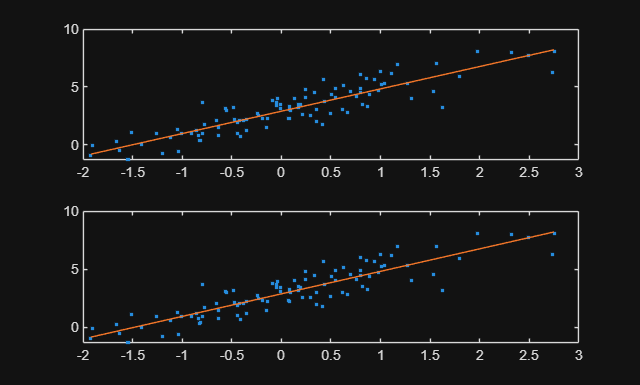



% Plot and compare predictions
figure
subplot(2,1,1)
plot(X,Y,'.',X,mdl.Fitted, '-')
subplot(2,1,2)
plot(X,Y,'.',X,ypred, '-')

## Exercise 2 :  Linear Regression with dim=2

Find the linear regression. Remove Outlier and predict a test value Xtest=[2;1];.  You can use MATLAB fitlm()

- Feature: 2-Dimensions,  p=2

- True value: y = 2*X1+4*X2+3

### **Data Acquisition**

X = randn(100,2);
y = X*[2;4] + 3+ randn(100,1);

### **Fit  Linear Regression**

mdl= fitlm(X,Y)   

mdl = 선형 회귀 모델:
    y ~ 1 + x1 + x2

추정된 계수:
                   Estimate       SE        tStat        pValue  
                   _________    _______    ________    __________

    (Intercept)       3.0785    0.21976      14.009    4.9023e-25
    x1              -0.22865    0.22297     -1.0255       0.30768
    x2             -0.044789    0.19814    -0.22604       0.82164


관측값 개수: 100, 오차 자유도: 97
RMS 오차: 2.17
결정계수: 0.0122, 수정된 결정계수: -0.00813
상수 모델에 대한 F-통계량: 0.601, p-값 = 0.55

### **Analyze**

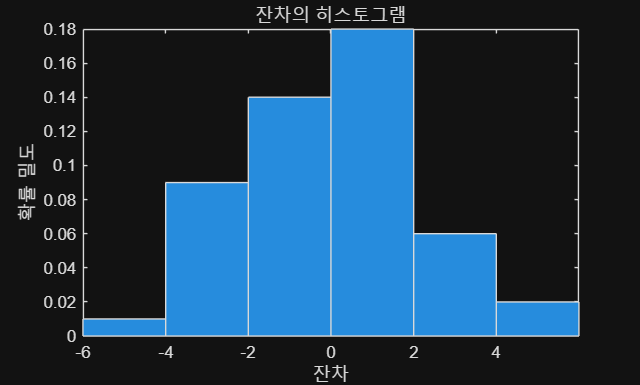

% Remove outlier
%  -plot residual histogram
figure
plotResiduals(mdl)


% - remove outlier from histogram analysis
outl = find(abs(mdl.Residuals.Raw) > 2);

% Fit linear regression (fitlm)
mdl2 = fitlm(X,Y,'Exclude',outl);


### **Predict**

Predict for a Test value

Xnew=[2, 1];
[Ynew,YnewI]= predict(mdl2, Xnew)

Ynew = 2.8195

YnewI =     2.1892    3.4499


## Exercise 3:  Linear Regression with dim=4

Find linear relationship of 

- MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight 

Choose a test data and predict

### **Data Acquisition**

clear
load carsmall

tbl = table(MPG,Acceleration,Displacement,Horsepower,Weight);

### **Fit  Linear Regression**

mdl = fitlm(tbl, 'MPG~Acceleration+Displacement+Horsepower+Weight')

mdl = 선형 회귀 모델:
    MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight

추정된 계수:
                     Estimate        SE         tStat        pValue  
                    __________    _________    ________    __________

    (Intercept)         48.117       3.9008      12.335    6.9194e-21
    Acceleration     -0.060312      0.21167    -0.28493       0.77636
    Displacement    -0.0066826     0.011594    -0.57638       0.56583
    Horsepower       -0.037547     0.026139     -1.4364       0.15442
    Weight           -0.006084    0.0013823     -4.4014      3.01e-05


관측값 개수: 93, 오차 자유도: 88
RMS 오차: 4.11
결정계수: 0.753, 수정된 결정계수: 0.742
상수 모델에 대한 F-통계량: 67.1, p-값 = 6.49e-26

### **Analyze**

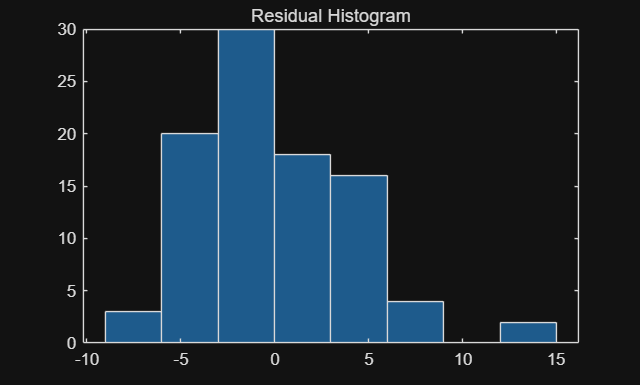

% Remove outlier    
%  -plot residual histogram
figure
histogram(mdl.Residuals.Raw)
title('Residual Histogram')


% - remove outlier from histogram analysis
outl = find(abs(mdl.Residuals.Raw) > 10);


% Fit linear regression (fitlm)
mdl2 = fitlm(tbl, 'Exclude',outl)

mdl2 = 선형 회귀 모델:
    Weight ~ 1 + MPG + Acceleration + Displacement + Horsepower

추정된 계수:
                    Estimate      SE        tStat       pValue  
                    ________    _______    _______    __________

    (Intercept)      1518.8         523      2.904     0.0046819
    MPG             -32.575      8.2575    -3.9449    0.00016242
    Acceleration     57.315      15.344     3.7354    0.00033631
    Displacement     3.4248     0.81716     4.1911    6.7043e-05
    Horsepower       5.9666      1.7691     3.3727     0.0011175


관측값 개수: 91, 오차 자유도: 86
RMS 오차: 288
결정계수: 0.879, 수정된 결정계수: 0.874
상수 모델에 대한 F-통계량: 157, p-값 = 1.27e-38

### **Predict**

Predict for a Test value

Xnew = [10 300 150 3500];

[Ynew,YnewI] = predict(mdl2, Xnew)

Ynew = 3.9784e+04

YnewI = 1.0e+04 *

    2.3209    5.6360
